# Train Self-Balancing Bicycle Using Reinforcement Learning Agents

Load the parameters of the model into the MATLAB® workspace.

config

Open Simulink Model

model = 'BikeRLAgent';
open_system(model)

## **Create Environment Interface**

Create the observation specification.

numObs = 15;
obsInfo = rlNumericSpec([numObs 1]);
obsInfo.Name = "observations";

Create the action specification.

numAct = 1;
actInfo = rlNumericSpec([numAct 1],LowerLimit=-1,UpperLimit=1);
actInfo.Name = "actions";

Create the environment interface for the walking robot model.

blk = model + "/RL Agent";
env = rlSimulinkEnv(model,blk,obsInfo,actInfo);
env.ResetFcn = @(in) ResetFcn(in, ...
    path_n_points, ...
    path_max_dim, ...
    cvx_hull_n_points ...
    );

## Create Agent for Training

Build the Critic Network

criticLayerSizes = [400 300];

statePath = [
    featureInputLayer(numObs,'Normalization','none','Name', 'observation')
    fullyConnectedLayer(criticLayerSizes(1), 'Name', 'CriticStateFC1', ... 
            'Weights',2/sqrt(numObs)*(rand(criticLayerSizes(1),numObs)-0.5), ...
            'Bias',2/sqrt(numObs)*(rand(criticLayerSizes(1),1)-0.5))
    reluLayer('Name','CriticStateRelu1')
    fullyConnectedLayer(criticLayerSizes(2), 'Name', 'CriticStateFC2', ...
            'Weights',2/sqrt(criticLayerSizes(1))*(rand(criticLayerSizes(2),criticLayerSizes(1))-0.5), ... 
            'Bias',2/sqrt(criticLayerSizes(1))*(rand(criticLayerSizes(2),1)-0.5))
    ];
actionPath = [
    featureInputLayer(numAct,'Normalization','none', 'Name', 'action')
    fullyConnectedLayer(criticLayerSizes(2), 'Name', 'CriticActionFC1', ...
            'Weights',2/sqrt(numAct)*(rand(criticLayerSizes(2),numAct)-0.5), ... 
            'Bias',2/sqrt(numAct)*(rand(criticLayerSizes(2),1)-0.5))
    ];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(1, 'Name', 'CriticOutput',...
            'Weights',2*5e-3*(rand(1,criticLayerSizes(2))-0.5), ...
            'Bias',2*5e-3*(rand(1,1)-0.5))
    ];

% Connect the layer graph
criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork, actionPath);
criticNetwork = addLayers(criticNetwork, commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

Build the Actor Network

actorLayerSizes = [400 300];
actorNetwork = [
    featureInputLayer(numObs,'Normalization','none','Name','observation')
    fullyConnectedLayer(actorLayerSizes(1), 'Name', 'ActorFC1', ...
            'Weights',2/sqrt(numObs)*(rand(actorLayerSizes(1),numObs)-0.5), ... 
            'Bias',2/sqrt(numObs)*(rand(actorLayerSizes(1),1)-0.5))
    reluLayer('Name', 'ActorRelu1')
    fullyConnectedLayer(actorLayerSizes(2), 'Name', 'ActorFC2', ... 
            'Weights',2/sqrt(actorLayerSizes(1))*(rand(actorLayerSizes(2),actorLayerSizes(1))-0.5), ... 
            'Bias',2/sqrt(actorLayerSizes(1))*(rand(actorLayerSizes(2),1)-0.5))
    reluLayer('Name', 'ActorRelu2')
    fullyConnectedLayer(numAct, 'Name', 'ActorFC3', ... 
                       'Weights',2*5e-3*(rand(numAct,actorLayerSizes(2))-0.5), ... 
                       'Bias',2*5e-3*(rand(numAct,1)-0.5))                       
    tanhLayer('Name','ActorTanh1')
    ];

Set Hyperparams

%% Specify options for the critic and actor representations using rlOptimizerOptions
criticOptions = rlOptimizerOptions('Optimizer','adam','LearnRate',1e-3,... 
                                        'GradientThreshold',1,'L2RegularizationFactor',2e-4);
actorOptions = rlOptimizerOptions('Optimizer','adam','LearnRate',1e-3,...
                                       'GradientThreshold',1,'L2RegularizationFactor',1e-5);

%% Create critic and actor representations using specified networks and
% options
critic = rlQValueFunction(criticNetwork,obsInfo,actInfo,'ObservationInputNames','observation','ActionInputNames','action');
actor  = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

%% Specify DDPG agent options
agentOptions = rlDDPGAgentOptions;
agentOptions.SampleTime = Ts;
agentOptions.DiscountFactor = DiscountFactor;
agentOptions.MiniBatchSize = MiniBatchSize;
agentOptions.ExperienceBufferLength = 1e6;
agentOptions.TargetSmoothFactor = 5e-3;
% agentOptions.NoiseOptions.MeanAttractionConstant = 1;
% agentOptions.NoiseOptions.Variance = 0.1;
agentOptions.ActorOptimizerOptions = actorOptions;
agentOptions.CriticOptimizerOptions = criticOptions;

%% Create agent using specified actor representation, critic representation and agent options
agent = rlDDPGAgent(actor,critic,agentOptions);

## Specify Training Options

maxEpisodes = trainingMaxEpisodes;
maxSteps = floor(Tf/Ts);
trainOpts = rlTrainingOptions(...
    MaxEpisodes=maxEpisodes,...
    MaxStepsPerEpisode=maxSteps,...
    ScoreAveragingWindowLength=250,...
    Verbose=false,...
    Plots="training-progress",...
    StopTrainingCriteria="EpisodeCount",...
    StopTrainingValue=maxEpisodes,...
    SaveAgentCriteria="EpisodeFrequency",...
    SaveAgentValue=500, ...
    SaveAgentDirectory = pwd + "\CandidateAgents");

To train the agent in parallel, specify the following training options. Training in parallel requires Parallel Computing Toolbox™. If you do not have Parallel Computing Toolbox software installed, set `UseParallel` to `false`.

- Set the `UseParallel` option to t`rue`.

- Train the agent in parallel asynchronously.

- After every 32 steps, have each worker send experiences to the parallel pool client (the MATLAB® process which starts the training). DDPG and TD3 agents require workers to send experiences to the client.

trainOpts.UseParallel = false;

if trainOpts.UseParallel
    trainOpts.ParallelizationOptions.Mode = "async";
    trainOpts.ParallelizationOptions.StepsUntilDataIsSent = 32;
    trainOpts.ParallelizationOptions.DataToSendFromWorkers = "Experiences";
end

## Train Agent

Turn on the visualization of the environment during training

USE_PRE_TRAINED_MODEL = false;

% Set agent option parameter:
agentOpts.ResetExperienceBufferBeforeTraining = not(USE_PRE_TRAINED_MODEL);

set_param(model,'SimMechanicsOpenEditorOnUpdate','off');

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. This process is computationally intensive and takes several hours to complete for each agent. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining `to `true`. Due to randomness in the parallel training, you can expect different training results from the plots that follow. The pretrained agents were trained in parallel using four workers.

doTraining = false;
if doTraining
    % Train the agent.8im
    trainingStats = train(agent,env,trainOpts);
end

## Simulate Trained Agents

Load trained model

set_param(model,'SimMechanicsOpenEditorOnUpdate','on');
load("CandidateAgents/FinalAgent.mat","agent")

Fix the random generator seed for reproducibility.

rng(5)

To validate the performance of the trained agent, simulate it within the biped robot environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

simOptions = rlSimulationOptions(MaxSteps=5*maxSteps);
experience = sim(env,agent,simOptions);

Found algebraic loop containing: 
BikeRLAgent/env/Blue Bike/Rear Wheel/Tyre model/Camber thrust/Dot Product1
BikeRLAgent/env/Blue Bike/Rear Wheel/Tyre model/Camber thrust/Trigonometric Function
BikeRLAgent/env/Config/Solver Configuration/EVAL_KEY/INPUT_4_1_1
BikeRLAgent/env/Config/Solver Configuration/EVAL_KEY/STATE_1
BikeRLAgent/env/Config/Solver Configura

Plot the bike trajectory as well as the reference path.

bike_x = getElement(experience.SimulationInfo.yout, "bike_x").Values.Data

bike_x =    -0.0000
    0.0001
    0.0007
    0.0038
    0.0097
    0.0155
    0.0211
    0.0267
    0.0318
    0.0365


bike_y = getElement(experience.SimulationInfo.yout, "bike_y").Values.Data

bike_y =     0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000



path_x = getElement(experience.SimulationInfo.yout, "path_x").Values.Data

path_x =          0    1.8505    3.4547    4.7703    5.8913    6.9461    8.0628    9.3697   10.9950   13.0670   15.6523   18.5710   21.5815   24.4422   26.9116   28.7482   29.7103   29.6228   28.5761   26.7271   24.2328   21.2498   17.9350   14.4454   10.9201    7.4272    4.0173    0.7409   -2.3516   -5.2094   -7.7823  -10.0196  -11.8709  -13.2857  -14.2133  -14.6034  -14.4054  -13.5688  -13.5688  -14.7301  -15.2197  -15.1140  -14.4896  -13.4230  -11.9906  -10.2690   -8.3347   -6.2641   -4.1338   -2.0203


path_y = getElement(experience.SimulationInfo.yout, "path_y").Values.Data

path_y =          0    0.0286   -0.0000   -0.1636   -0.3172   -0.2597    0.2097    1.2919    3.1880    6.0988   10.1332   15.0323   20.4451   26.0207   31.4082   36.2564   40.2146   43.0294   44.8383   45.8762   46.3783   46.5796   46.7152   47.0201   47.6723   48.6211   49.7586   50.9770   52.1683   53.2247   54.0384   54.5015   54.5061   53.9443   52.7084   50.6904   47.7824   43.8767   43.8767   34.1604   25.9916   19.2367   13.7618    9.4334    6.1175    3.6807    1.9890    0.9088    0.3064    0.0480


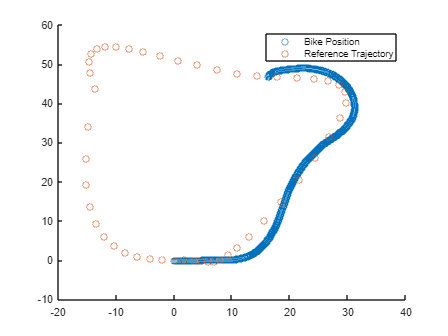


scatter(bike_x, bike_y)
hold on

scatter(path_x, path_y)
legend("Bike Position", "Reference Trajectory")
hold off

save("CandidateAgents\FinalAgent.mat", "agent")